# DIMENSIONALITY REDUCTION - Multidimensional Scaling

## DATA DOWNLOAD and LOADING

#### Begin by obtaining the MNIST [1] image and label data from

####     [http://yann.lecun.com/exdb/mnist/](http://yann.lecun.com/exdb/mnist/)

####  Unzip the files. For this example, use the "t10k-images" data.

clc; close all; clear

imageFileName = 't10k-images.idx3-ubyte';
labelFileName = 't10k-labels.idx1-ubyte';

%%
% Process the files to load them in the workspace. The code for this
% processing function appears at the end of this example. To execute the
% code, add the directory of the function to the search path.
addpath(fullfile(matlabroot,'examples','stats')); % add to the path
[X,L] = processMNISTdata(imageFileName,labelFileName);


Read MNIST image data...
Number of images in the dataset:  10000 ...
Each image is of 28 by 28 pixels...
The image data is read to a matrix of dimensions:  10000 by  784...
End of reading image data.

Read MNIST label data...
Number of labels in the dataset:  10000 ...
The label data is read to a matrix of dimensions:  10000 by  1...
End of reading label data.


rmpath(fullfile(matlabroot,'examples','stats')); % remove from the path


## Process Data Using PCA

**Extraction of the first three principal components, which explains almost 30-40% of the variance in data**

[pcs,scrs,~,~,expl] = pca(X);

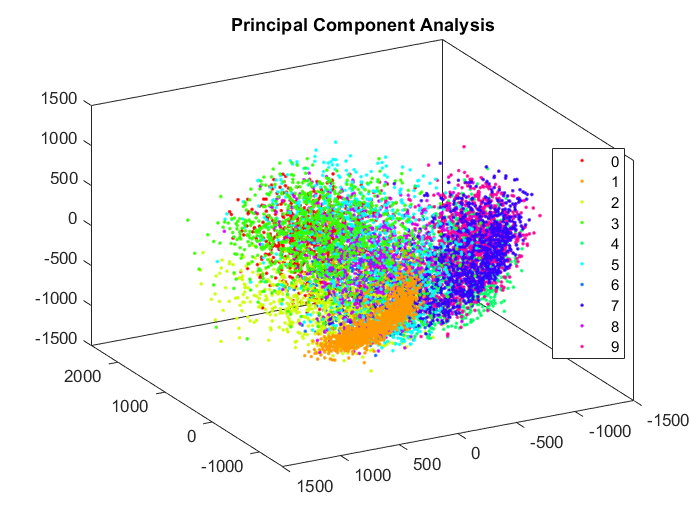

% pareto(expl)
% xlim([0 50.5])
figure
h = gscatter(scrs(:,1), scrs(:,2),L);
% for each unique group in 'g', set the ZData property appropriately
gu = unique(L);
z = scrs(:,3);
for k = 1:numel(gu)
      set(h(k), 'ZData', z( L == gu(k) ));
end
view(3)
title('Principal Component Analysis')

view([-119 30])

## **Process Data Using Multidimensional Scaling**

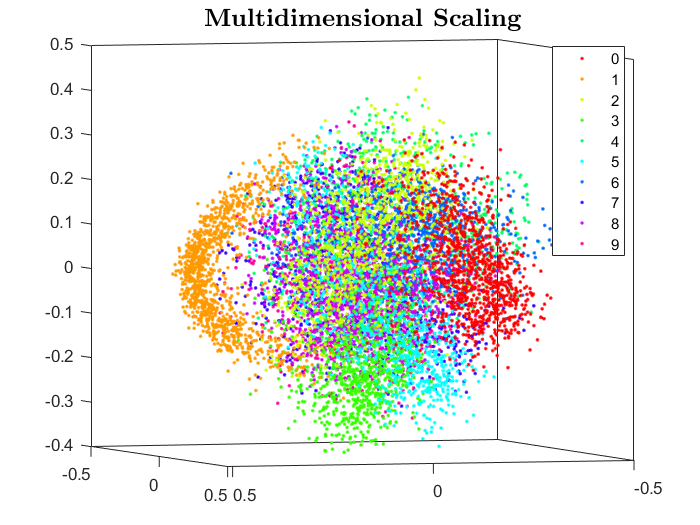

figure
D = pdist(X,"cosine");
[xRed, e] = cmdscale(D);

h2 = gscatter(xRed(:,1), xRed(:,2),L);
% for each unique group in 'g', set the ZData property appropriately
gu = unique(L);
z = xRed(:,3);
for k = 1:numel(gu)
      set(h2(k), 'ZData', z( L == gu(k) ));
end
view(3)
title('\textbf{Multidimensional Scaling}','Interpreter','Latex',"FontSize",15)

view([161.425 3.073])

## Process Data Using t-SNE

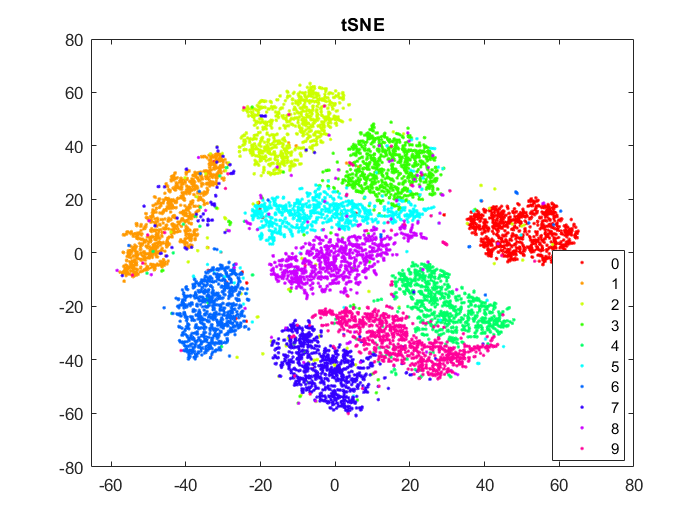

rng default % for reproducibility
Y = tsne(X,'Algorithm','barneshut');
figure
gscatter(Y(:,1),Y(:,2),L)
title('tSNE')

tsne with default settings does a good job of embedding the high-dimensional initial data into two-dimensional points that have well defined clusters. The effects of algorithm settings are difficult to predict. Sometimes they can improve the clustering, but for the most part the default settings seem good

References

[1] Yann LeCun (Courant Institute, NYU) and Corinna Cortes (Google Labs, New York) hold the copyright of MNIST dataset, which is a derivative work from original NIST datasets. MNIST dataset is made available under the terms of the Creative Commons Attribution-Share Alike 3.0 license, https://creativecommons.org/licenses/by-sa/3.0/

function [X,L] = processMNISTdata(imageFileName,labelFileName)

[fileID,errmsg] = fopen(imageFileName,'r','b');
if fileID < 0
    error(errmsg);
end
%%
% First read the magic number. This number is 2051 for image data, and
% 2049 for label data
magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2051
    fprintf('\nRead MNIST image data...\n')
end
%%
% Then read the number of images, number of rows, and number of columns
numImages = fread(fileID,1,'int32',0,'b');
fprintf('Number of images in the dataset: %6d ...\n',numImages);
numRows = fread(fileID,1,'int32',0,'b');
numCols = fread(fileID,1,'int32',0,'b');
fprintf('Each image is of %2d by %2d pixels...\n',numRows,numCols);
%%
% Read the image data
X = fread(fileID,inf,'unsigned char');
%%
% Reshape the data to array X
X = reshape(X,numCols,numRows,numImages);
X = permute(X,[2 1 3]);
%%
% Then flatten each image data into a 1 by (numRows*numCols) vector, and 
% store all the image data into a numImages by (numRows*numCols) array.
X = reshape(X,numRows*numCols,numImages)';
fprintf(['The image data is read to a matrix of dimensions: %6d by %4d...\n',...
    'End of reading image data.\n'],size(X,1),size(X,2));
%%
% Close the file
fclose(fileID);
%%
% Similarly, read the label data.
[fileID,errmsg] = fopen(labelFileName,'r','b');
if fileID < 0
    error(errmsg);
end
magicNum = fread(fileID,1,'int32',0,'b');
if magicNum == 2049
    fprintf('\nRead MNIST label data...\n')
end
numItems = fread(fileID,1,'int32',0,'b');
fprintf('Number of labels in the dataset: %6d ...\n',numItems);

L = fread(fileID,inf,'unsigned char');
fprintf(['The label data is read to a matrix of dimensions: %6d by %2d...\n',...
    'End of reading label data.\n'],size(L,1),size(L,2));
fclose(fileID);

end